# Social modulated neurons analysis

### Summary for socially modulated neurons

file_path = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Social_modulation_240210_1.xlsx';
opts = detectImportOptions(file_path);
opts = setvartype(opts, 'RecDate', 'string');
T_social = readtable(file_path,opts);

self_land = T_social.self_land;
self_toff = T_social.self_toff;
other_land = T_social.other_land;
other_toff = T_social.other_toff;

unit_depth = T_social.Depth;
unit_fr     = T_social.fr;

n_session = length(unique(T_social.RecDate));
session_list = unique(T_social.RecDate);
animal_list = unique(T_social.Animal);

res = cell(length(session_list),5);
for ss=1:length(session_list)
    res{ss,1} = session_list{ss};
    % Self landing
    idx_all = strcmp(T_social.RecDate,session_list{ss}) & T_social.Animal == animal_list(1);
    n_all = sum(idx_all); n_social = sum(T_social.self_land(idx_all));
    res{ss,2} = 100*n_social/n_all;
    fprintf('[%s] Self landings: %.1f%% (%d/%d)\n',session_list{ss},100*n_social/n_all,n_social,n_all)
    
    % Self takeoffs
    idx_all = strcmp(T_social.RecDate,session_list{ss}) & T_social.Animal == animal_list(1);
    n_all = sum(idx_all); n_social = sum(T_social.self_toff(idx_all));
    res{ss,3} = 100*n_social/n_all;
    fprintf('[%s] Self takeoffs: %.1f%% (%d/%d)\n',session_list{ss},100*n_social/n_all,n_social,n_all)
    
    % Others landings
    idx_all = strcmp(T_social.RecDate,session_list{ss}) & T_social.Animal == animal_list(1);
    n_all = sum(idx_all); n_social = sum(T_social.other_land(idx_all));
    res{ss,4} = 100*n_social/n_all;
    fprintf('[%s] Others'' landings: %.1f%% (%d/%d)\n',session_list{ss},100*n_social/n_all,n_social,n_all)
    
    % Others takeoffs
    idx_all = strcmp(T_social.RecDate,session_list{ss}) & T_social.Animal == animal_list(1);
    n_all = sum(idx_all); n_social = sum(T_social.other_toff(idx_all));
    res{ss,5} = 100*n_social/n_all;
    fprintf('[%s] Others'' landings: %.1f%% (%d/%d)\n',session_list{ss},100*n_social/n_all,n_social,n_all)
end

[240207] Self landings: 20.0% (11/55)


[240207] Self takeoffs: 21.8% (12/55)


[240207] Others' landings: 16.4% (9/55)


[240207] Others' landings: 12.7% (7/55)


[240208] Self landings: 31.7% (13/41)


[240208] Self takeoffs: 12.2% (5/41)


[240208] Others' landings: 36.6% (15/41)


[240208] Others' landings: 31.7% (13/41)


[240209_1] Self landings: 23.8% (10/42)


[240209_1] Self takeoffs: 16.7% (7/42)


[240209_1] Others' landings: 21.4% (9/42)


[240209_1] Others' landings: 11.9% (5/42)


[240210_1] Self landings: 38.7% (12/31)


[240210_1] Self takeoffs: 25.8% (8/31)


[240210_1] Others' landings: 29.0% (9/31)


[240210_1] Others' landings: 9.7% (3/31)


[240212] Self landings: 22.7% (5/22)


[240212] Self takeoffs: 18.2% (4/22)


[240212] Others' landings: 13.6% (3/22)


[240212] Others' landings: 27.3% (6/22)


### Spatial distribution of socially modulated neurons

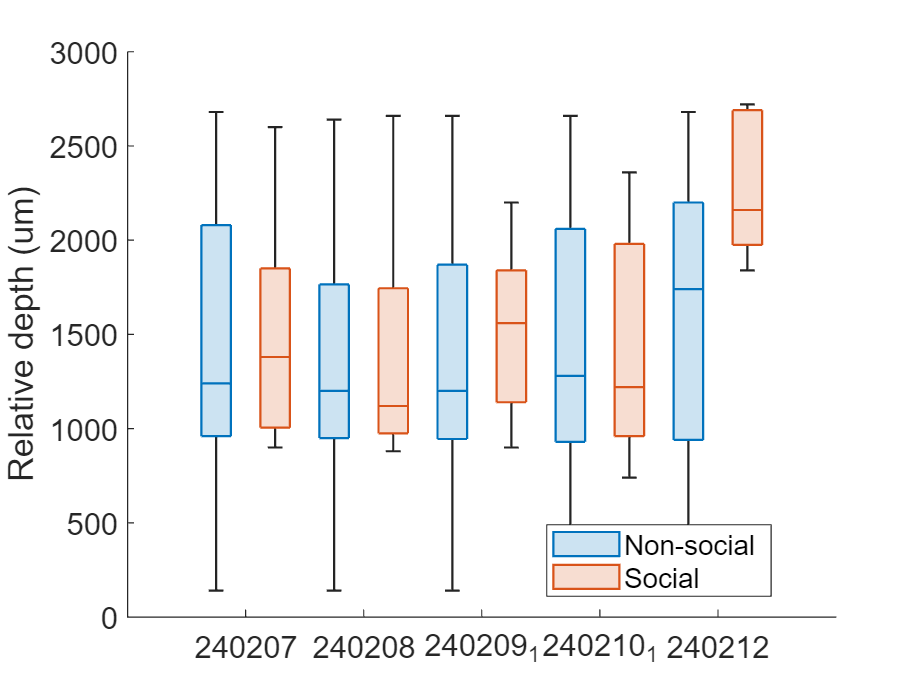

boxchart(categorical(T_social.RecDate),T_social.Depth,'GroupByColor',T_social.self_land)
ylabel('Relative depth (um)')
legend({'Non-social','Social'},'Location','best')
set(gca,'FontSize',14)

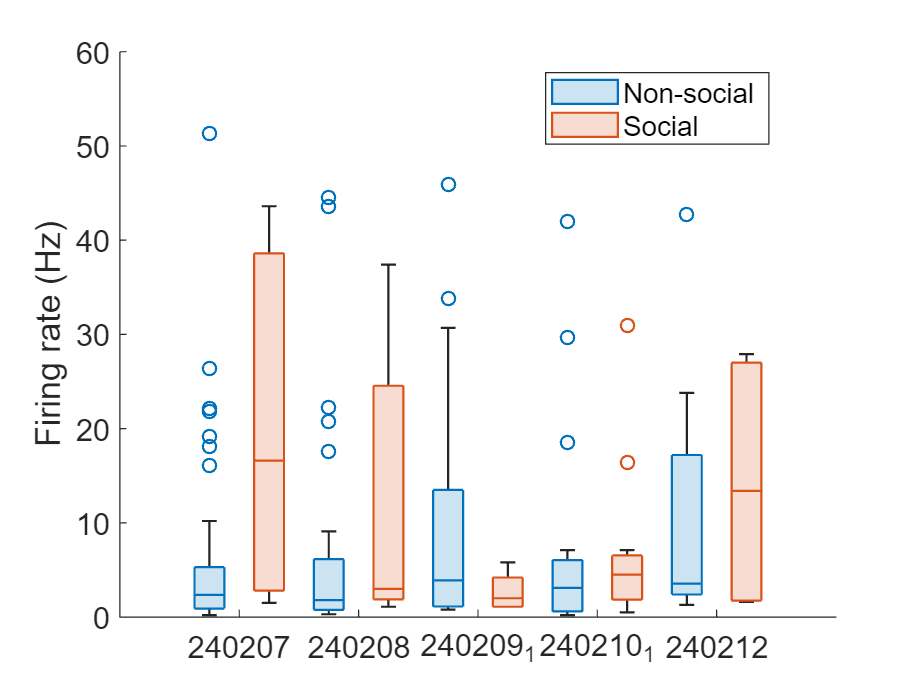


boxchart(categorical(T_social.RecDate),T_social.fr,'GroupByColor',T_social.self_land)
ylabel('Firing rate (Hz)')
legend({'Non-social','Social'},'Location','best')
set(gca,'FontSize',14)

### Cell types vs social modulation

file_path = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Social_modulation_240210_1.xlsx';
opts = detectImportOptions(file_path);
opts = setvartype(opts, 'RecDate', 'string');
T_social = readtable(file_path,opts);

